上机1

在本作业中,我们会回顾基础的线性代数以及图像操作方法,让大家更好地熟悉本课程.

本作业的一个目的是让大家熟悉常用的一些函数库. 因此在你所需要实现的函数里，你可以参考一下帮助文件.

好了，祝大家好运~~

# 问题1：线性代数回顾

在本节中，我们将会回顾一下线性代数的基本概念，并且学习来操作向量和矩阵。通过本节学习，你将会学会基本的矩阵操作。

## 问题 1.1 

首先, 让我们定义以下矩阵和向量. 

提示：可以参阅帮助文件. 在下一个code block中，将 M 定义成 [4,3] 的矩阵,a 定义成 [1,3] 的行向量， b 定义成 [3,1的]列向量

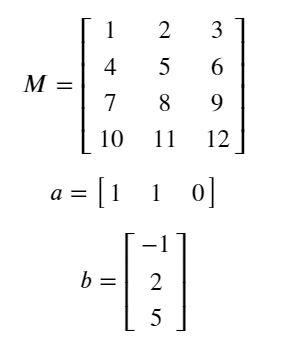

% 你的代码
 M= [1,2,3;   
     4,5,6; 
     7,8,9;
     10,11,12];  
a = [1,1,0];  
b = [-1;   
     2;
     5];
% 你的代码
disp('M=');disp(M);disp('The size of M is: ');disp(size(M));

M=
     1     2     3
     4     5     6
     7     8     9
    10    11    12

The size of M is: 
     4     3



disp('a=');disp(a);disp('The size of a is: ');disp(size(a));

a=
     1     1     0

The size of a is: 
     1     3



disp('b=');disp(b);disp('The size of b is: ');disp(size(b));

b=
    -1
     2
     5

The size of b is: 
     3     1



## 问题1.2：请计算向量的点积，即$a^T b$

% 你的代码
aDotB=dot(a.',b);
% 你的代码

disp('a点积b的计算结果是： ');

a点积b的计算结果是： 


disp(aDotB);

     1



## 问题1.3：请完成矩阵的乘法，即${\;a}^T b\;M\;a^T$

% 你的代码
result=aDotB*M;
result=result*a.';
% 你的代码

disp('计算结果是： ');

计算结果是： 


disp(result);

     3
     9
    15
    21



## 问题1.4：利用svd()函数计算矩阵M的奇异值

% 你的代码
result=svd(M);
% 你的代码
disp('矩阵的前两个奇异值是：');

矩阵的前两个奇异值是：


disp(result(1:2));

   25.4624
    1.2907



## 问题1.5：利用eig()函数计算矩阵MM的特征值及特征向量：


$$\textrm{MM}=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


% 你的代码
MM=[1,2,3;
    4,5,6;
    7,8,9];
[vec,val]=eig(MM);
% 你的代码
disp('Eigenvalues =');

Eigenvalues =


disp(val);

   16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000



disp('Eigenvectors =');

Eigenvectors =


disp(vec);

   -0.2320   -0.7858    0.4082
   -0.5253   -0.0868   -0.8165
   -0.8187    0.6123    0.4082



# 第二部分: 图像操作

现在你已经熟悉怎么利用matlab来操作矩阵和向量了. 现在让我们载入一些图片，将它们视作矩阵，并且对它们进行一些操作。

## 问题2.1：请载入图片image1以及图片image2并进行显示

image1_path = './image1.jpg'

image1_path = './image1.jpg'

image2_path = './image2.jpg'

image2_path = './image2.jpg'

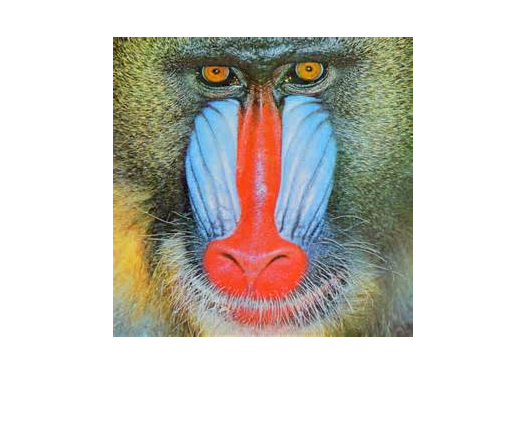


% 你的代码
img1=imread(image1_path);
img2=imread(image2_path);
imshow(img1);

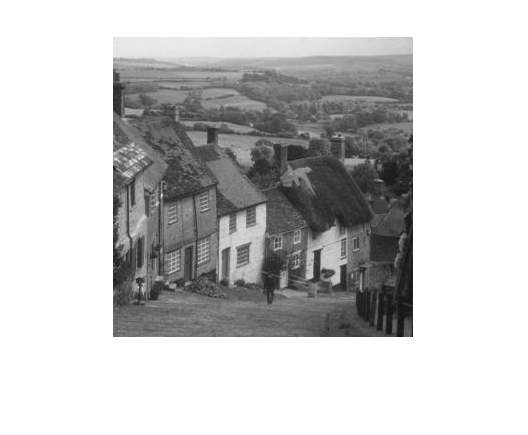

imshow(img2);

% 你的代码

## 问题 2.2

完成并运行函数 `dim_image()`，将每个像素点变为$x_n =0\ldotp 5*\;x_p^2$ , 其中$x_n$ 表示新的像素值 $x_p$ 表示原始像素值.

注意: 请先将原图像的像素值进行归一化到[0,1], 再按照上述公式使得像素值变小。进而整幅图片的亮度都会降低。

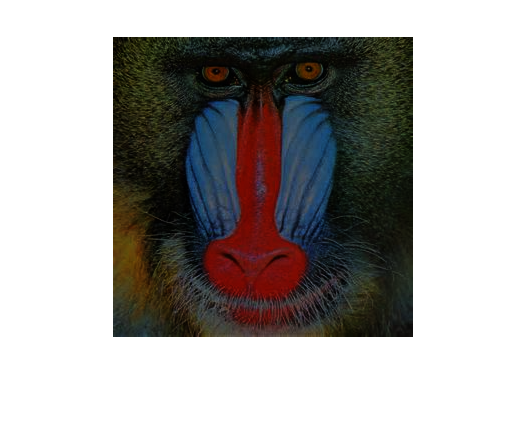

new_image = dim_image(img1);
imshow(new_image);

## 问题 2.3 

完成并运行`convert_to_grey_scale`函数，将图片转为灰度图。可以发现彩色图有三个通道，而灰度图只有一个通道。

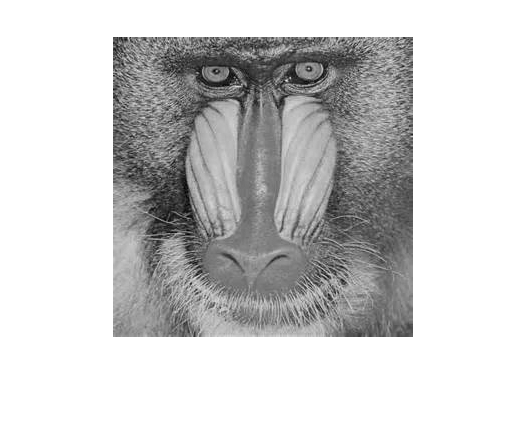

gray_image = convert_to_grey_scale(img1);
imshow(gray_image);

## 问题 2.4 

完成并运行函数 `rgb_exclusion(img,channel)`, 将输入图片分解为三个通道: R, G 以及 B。 同时将指定的通道从返回图片中去除。 

without_red = rgb_exclusion(img1, 'R')

without_red = without_red(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

without_green = rgb_exclusion(img1, 'G')

without_green = without_green(:,:,1) =

    0.3569    0.3176    0.3686    0.3765    0.2157    0.4549    0.2745    0.2667    0.1294    0.4196    0.4784    0.2784    0.2863    0.2157    0.4980    0.8196    0.5137    0.1961    0.6000    0.5176    0.5137    0.4902    0.4118    0.3882    0.4510    0.6118    0.6392    0.6235    0.4471    0.4392    0.3451    0.3255    0.3765    0.5137    0.6588    0.6275    0.5294    0.5569    0.5176    0.3412    0.6824    0.7059    0.3451    0.2471    0.6275    0.4196    0.4902    0.4431    0.5882    0.4275    0.3412    0.3373    0.3529    0.6588    0.5176    0.2510    0.3412    0.4314    0.5137    0.4627    0.5647    0.2471    0.2745    0.3569    0.5922    0.5059    0.6235    0.6980    0.7020    0.6118    0.2980    0.6471    0.6745    0.6824    0.5412    0.6667    0.3804    0.6431    0.3529    0.2275    0.3020    0.3961    0.3843    0.5412    0.4863    0.4549    0.4353    0.4314    0.4157    0.5294    0.4471    0.3647    0.2471    0.3765    0.2353    0.4667

without_blue = rgb_exclusion(img1, 'B')

without_blue = without_blue(:,:,1) =

    0.3569    0.3176    0.3686    0.3765    0.2157    0.4549    0.2745    0.2667    0.1294    0.4196    0.4784    0.2784    0.2863    0.2157    0.4980    0.8196    0.5137    0.1961    0.6000    0.5176    0.5137    0.4902    0.4118    0.3882    0.4510    0.6118    0.6392    0.6235    0.4471    0.4392    0.3451    0.3255    0.3765    0.5137    0.6588    0.6275    0.5294    0.5569    0.5176    0.3412    0.6824    0.7059    0.3451    0.2471    0.6275    0.4196    0.4902    0.4431    0.5882    0.4275    0.3412    0.3373    0.3529    0.6588    0.5176    0.2510    0.3412    0.4314    0.5137    0.4627    0.5647    0.2471    0.2745    0.3569    0.5922    0.5059    0.6235    0.6980    0.7020    0.6118    0.2980    0.6471    0.6745    0.6824    0.5412    0.6667    0.3804    0.6431    0.3529    0.2275    0.3020    0.3961    0.3843    0.5412    0.4863    0.4549    0.4353    0.4314    0.4157    0.5294    0.4471    0.3647    0.2471    0.3765    0.2353    0.4667  

disp(size(without_red));

   300   300     3




disp('下图去除了Red通道.');

下图去除了Red通道.


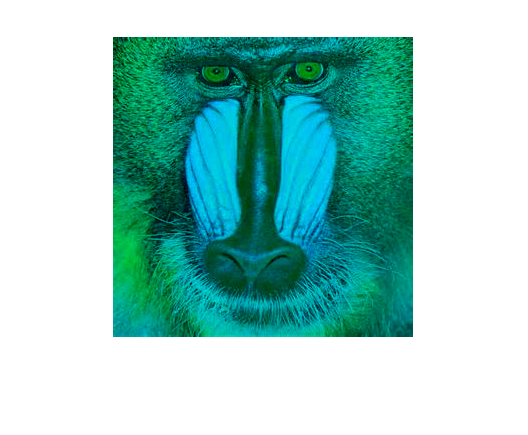

imshow(without_red);


disp('下图去除了Green通道.');

下图去除了Green通道.


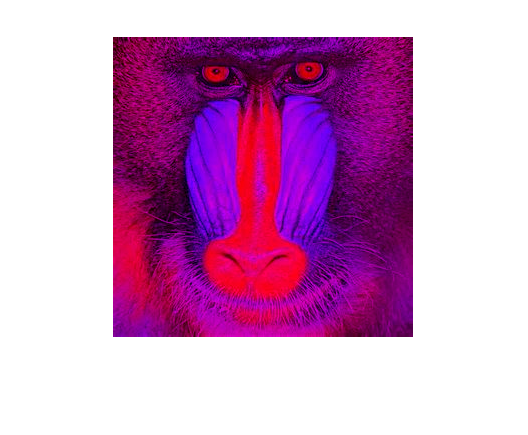

imshow(without_green);


disp('下图去除了Blue通道.');

下图去除了Blue通道.


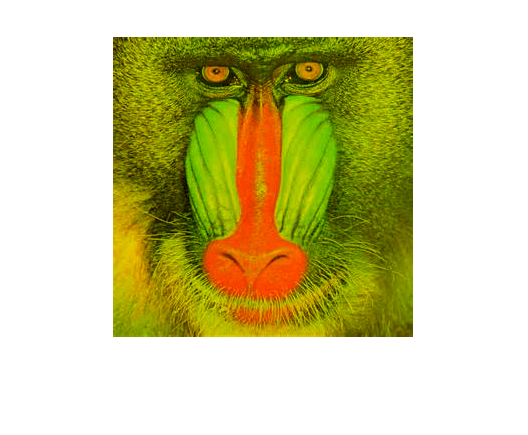

imshow(without_blue);

## 问题 2.5

完成并运行函数 `lab_decomposition`, 将输入图片分解为L,A,B三个通道，返回指定的通道图片。

image_l = lab_decomposition(img1, 'L');
image_a = lab_decomposition(img1, 'A');
image_b = lab_decomposition(img1, 'B');


disp('只有 L 通道.');

只有 L 通道.


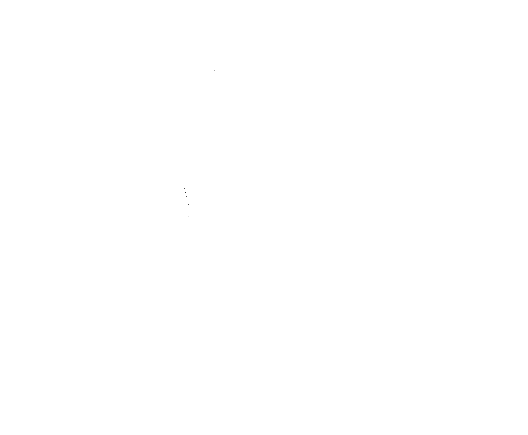

imshow(image_l);


disp('只有 a 通道.');

只有 a 通道.


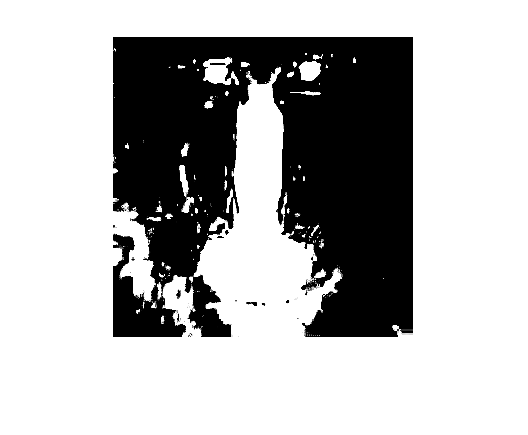

imshow(image_a);


disp('只有 b 通道.');

只有 b 通道.


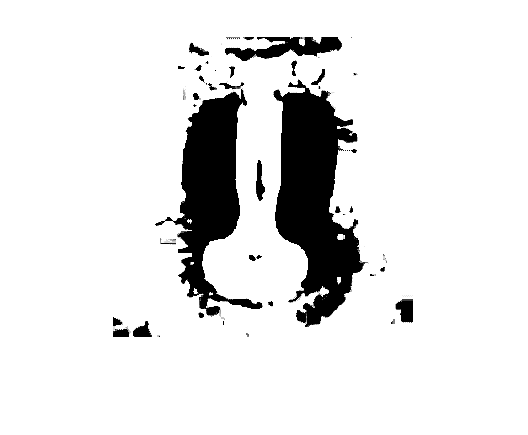

imshow(image_b);

## 问题:

用一两句话解释一下Lab分别代表什么，同时如果拿掉L通道和a通道，会发生什么？

## 你的答案:

L代表亮度，它描述了颜色的明暗程度，与图像的亮度信息相关。A和B代表色度，它们共同描述了颜色的色相和饱和度信息，其中A通道通常与从绿色到红色的颜色变化相关，而B通道与从蓝色到黄色的颜色变化相关。

如果拿掉L通道和a通道，只留下B通道，图像将失去大部分的亮度信息和一部分色度信息（特别是与绿色到红色的变化相关的信息）。

## 问题 2.6 

完成并运行函数 `hsv_decomposition()`, 将输入图片分解成 H, S 以及 V 三个通道，并且返回指定的图像通道。 

image_h = hsv_decomposition(img1, 'H');
image_s = hsv_decomposition(img1, 'S');
image_v = hsv_decomposition(img1, 'V');

disp('只有 H 通道.');

只有 H 通道.


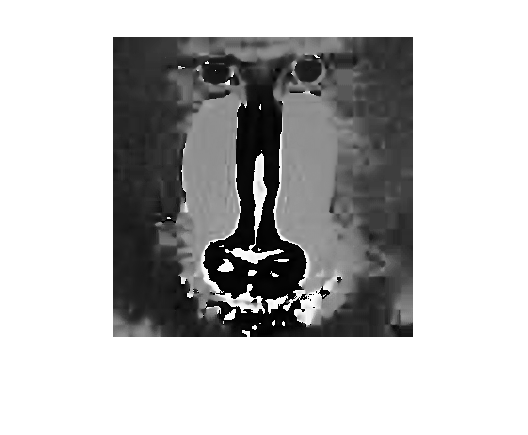

imshow(image_h);


disp('只有 S 通道.');

只有 S 通道.


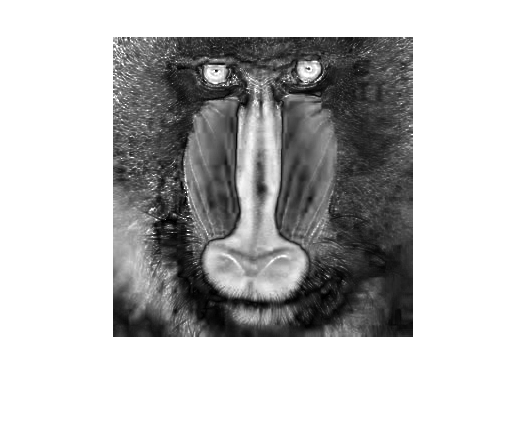

imshow(image_s);


disp('只有 V 通道.');

只有 V 通道.


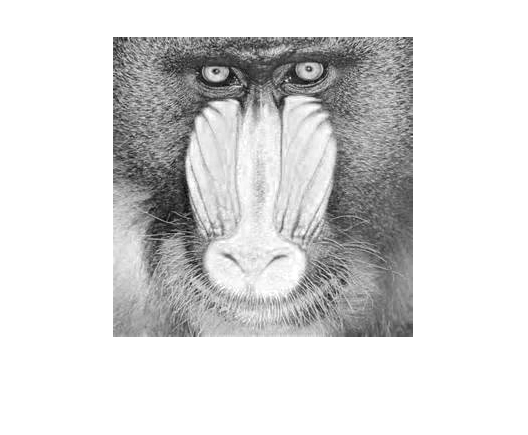

imshow(image_v);

## 问题:

用一两句话解释一下H S V分别代表什么，同时如果拿掉H通道和S通道，会发生什么？

## 你的答案:

H代表色调，它描述了颜色的种类，如红色、蓝色或绿色等。色调是区分不同颜色的关键属性。S代表饱和度，它描述了颜色的纯度或鲜艳程度。饱和度越高，颜色越鲜艳；饱和度越低，颜色越接近灰色。V代表明度或亮度，它描述了颜色的明亮程度。明度越高，颜色越亮；明度越低，颜色越暗。

如果拿掉H通道和S通道，只留下V通道，图像将失去所有的颜色信息，只保留亮度信息。这会导致图像呈现为灰度图，因为灰度图只包含亮度信息，而不包含色调和饱和度信息。

## 问题 2.7 

完成并运行函数 `mix_images`：创建一幅新的图片，使得它的左半部分是图片1，右半部分是图片2，并且去掉指定的图像通道（R,G,或者B）。 

你会看到新图像的左半部分是猴子，并且没有红色通道，而图像的右半部分是一间房子，并且没有绿色通道。

提示：两张图像的尺寸是一样的，因此不需要进行额外的像素填充。

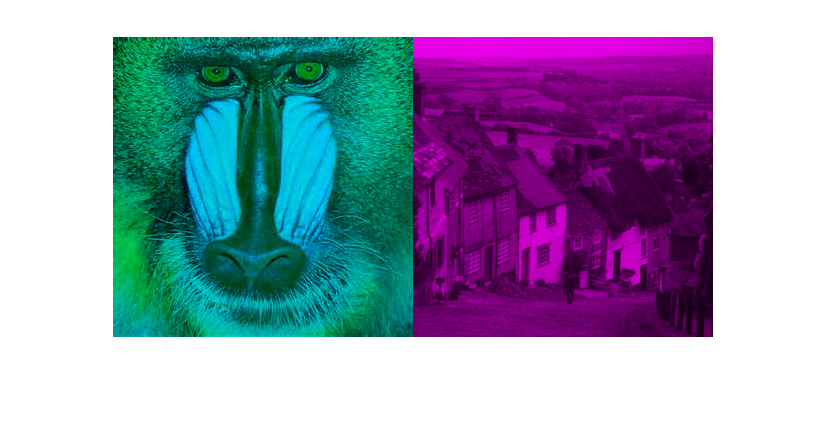

image_mixed = mix_images(img1, img2, 'R', 'G');
imshow(image_mixed);

## 问题 2.8

完成并运行`mix_quadrants`函数。

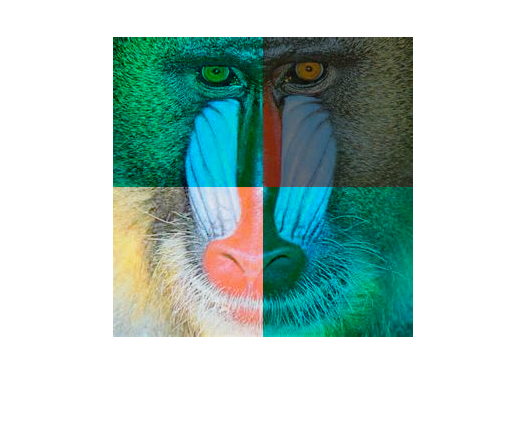

mixed_quadrants = mix_quadrants(img1);
imshow(mixed_quadrants);